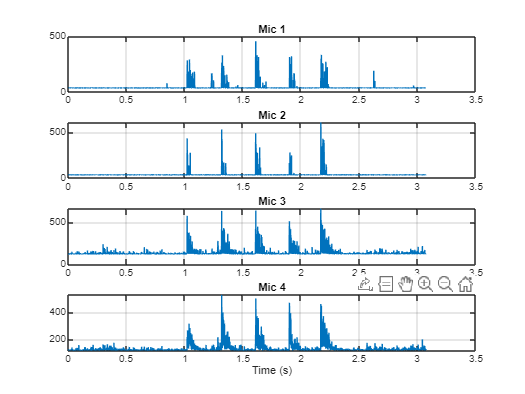

clc; clear; close all;

% Load CSV
data = readmatrix('demo_sui6');

mic1 = data(:,1);
mic2 = data(:,2);
mic3 = data(:,3);
mic4 = data(:,4);


Fs = 1650;              % Sampling frequency (Hz)
Ts = 1/Fs;               % Sampling period
N = length(mic1);        % Number of samples
% N = 5000;
t = (0:N-1)*Ts;          % Time vector

% mic1 = mic1(4001:N);
% mic2 = mic2(4001:N);
% mic3 = mic3(4001:N);
% mic4 = mic4(4001:N);
figure;

subplot(4,1,1);
plot(t, mic1);
title('Mic 1'); grid on;

subplot(4,1,2);
plot(t, mic2);
title('Mic 2'); grid on;

subplot(4,1,3);
plot(t, mic3);
title('Mic 3'); grid on;

subplot(4,1,4);
plot(t, mic4);
title('Mic 4'); grid on;

xlabel('Time (s)');

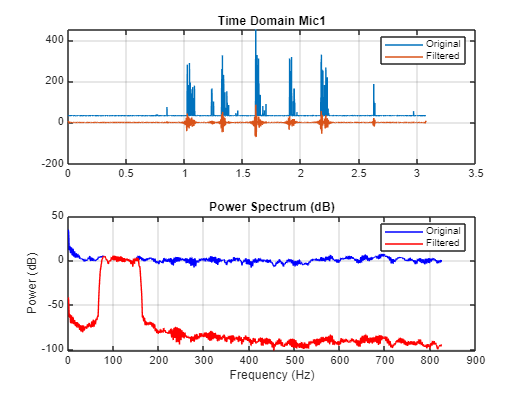

% Lowpass
mic1_f = bandpass(mic1, [80 150], Fs);
mic2_f = bandpass(mic2, [80 150], Fs);
mic3_f = bandpass(mic3, [80 150], Fs);
mic4_f = bandpass(mic4, [80 150], Fs);

% Mic 1
figure;
subplot(2,1,1);
plot(t, mic1); hold on;
plot(t, mic1_f);
title('Time Domain Mic1');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on;
plot(ff1, 10*log10(pf1), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

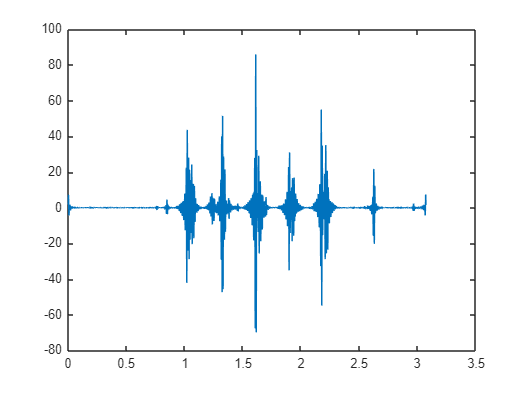

clf
plot(t,mic1_f)

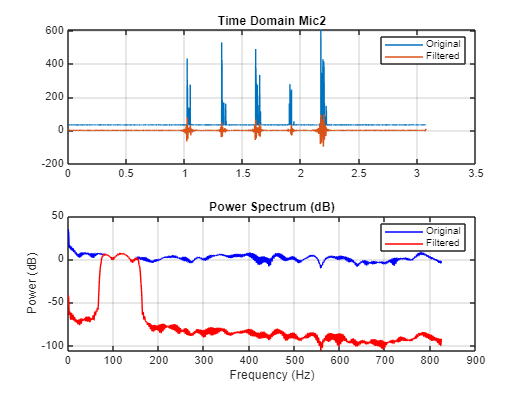


% Mic 2
figure;
subplot(2,1,1);
plot(t, mic2); hold on;
plot(t, mic2_f);
title('Time Domain Mic2');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), 'b'); hold on;
plot(ff2, 10*log10(pf2), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

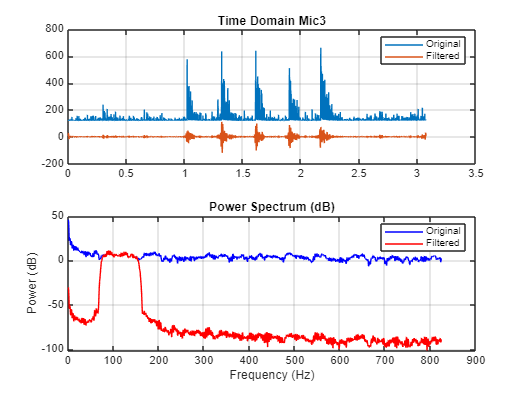


% Mic 3
figure;
subplot(2,1,1);
plot(t, mic3); hold on;
plot(t, mic3_f);
title('Time Domain Mic3');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po3,fo3] = pspectrum(mic3, Fs);
[pf3,ff3] = pspectrum(mic3_f, Fs);

plot(fo3, 10*log10(po3), 'b'); hold on;
plot(ff3, 10*log10(pf3), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

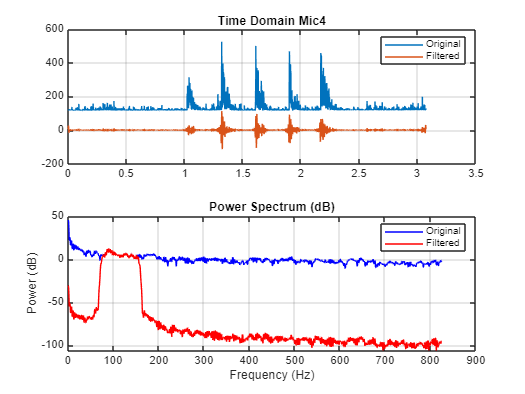


% Mic 4
figure;
subplot(2,1,1);
plot(t, mic4); hold on;
plot(t, mic4_f);
title('Time Domain Mic4');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po4,fo4] = pspectrum(mic4, Fs);
[pf4,ff4] = pspectrum(mic4_f, Fs);

plot(fo4, 10*log10(po4), 'b'); hold on;
plot(ff4, 10*log10(pf4), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

clf;

plot(t,mic1_f);

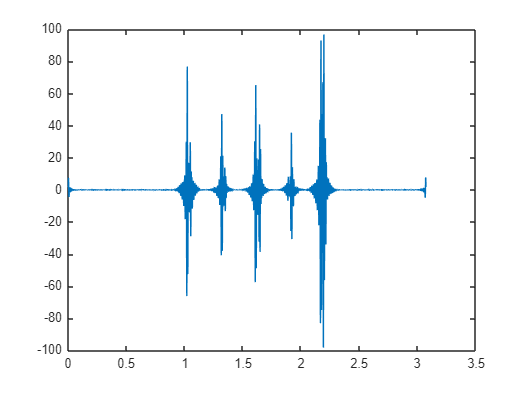

plot(t,mic2_f);

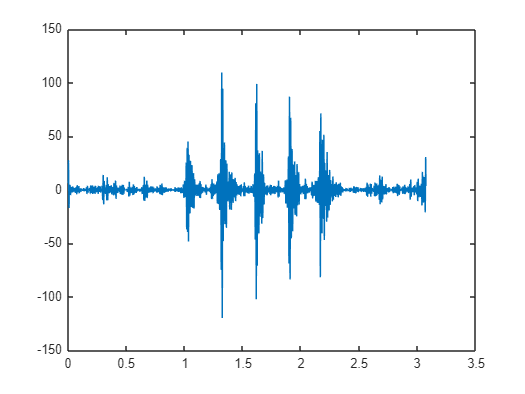

plot(t,mic3_f);

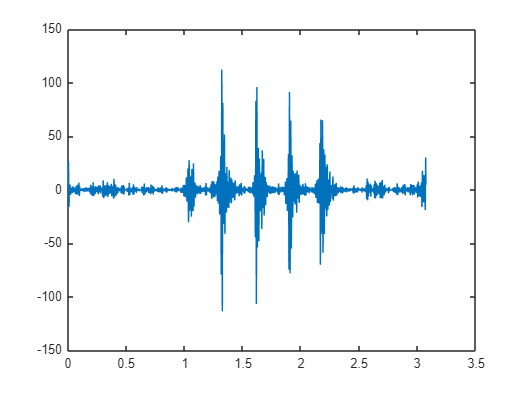

plot(t,mic4_f);

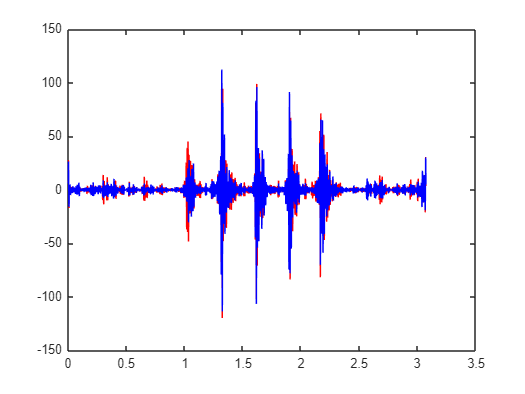


figure;
plot(t,mic3_f,"r")
hold on
plot(t,mic4_f,"b")
hold off

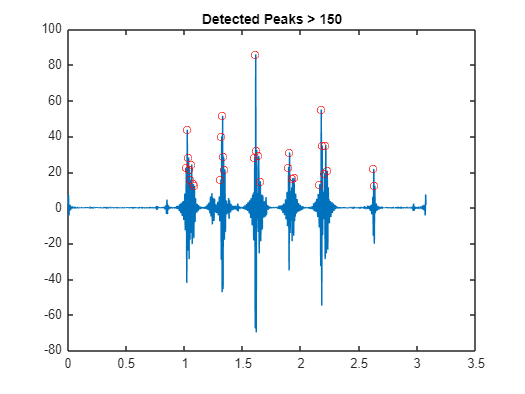


% This finds the values (pks) and their location in time (locs)
[pks, locs] = findpeaks(mic1_f, 'MinPeakHeight', 12);

% Plotting to verify
figure;
plot(t, mic1_f); hold on;
plot(t(locs), pks, 'ro'); % Marks the peaks with red circles
title('Detected Peaks > 150');

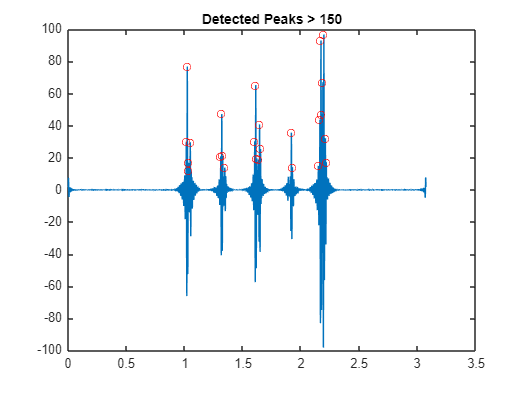


[pks2, locs2] = findpeaks(mic2_f, 'MinPeakHeight', 12);
figure;
plot(t, mic2_f); hold on;
plot(t(locs2), pks2, 'ro'); % Marks the peaks with red circles
title('Detected Peaks > 150');


% Calculate threshold based on the specific noise floor of each mic
thresh1 = 150; % 3 times the standard deviation
thresh2 = 150

thresh2 = 150

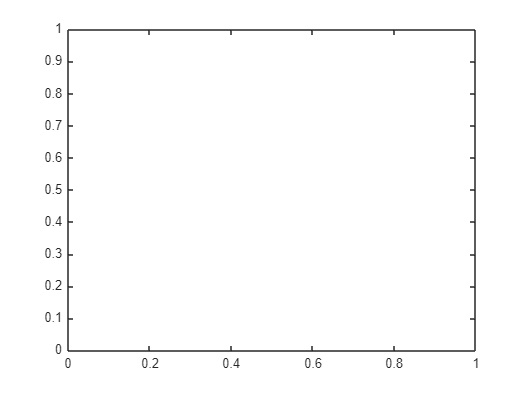


mic1_f(abs(mic1_f) < thresh1) = 0;
mic2_f(abs(mic2_f) < thresh1) = 0;
% Repeat for mic 3 and 4

% Normalize signals to have a max amplitude of 1
mic1_f = mic1_f / max(abs(mic1_f));
mic2_f = mic2_f / max(abs(mic2_f));

clf
plot(t,mic1_f);

plot(t,mic2_f);

plot(t,mic3_f);

plot(t,mic4_f);

% % Voice Activity Detection
% 
% window = 500;   % adjust based on Fs
% energy = movmean(mic1_f.^2, window); % cal energy
% 
% threshold = mean(energy) * 1; %cal mean at each window
% active_idx = energy > threshold; %check idex that mean higher than threshold
% 
% mic1_f = mic1_f(active_idx);
% mic2_f = mic2_f(active_idx);
% mic3_f = mic3_f(active_idx);
% mic4_f = mic4_f(active_idx);


% % Detect Speech
% clf;
% figure;
% [idx,thresholds] = detectSpeech(mic1_f, Fs)
% 
% detectSpeech(mic1_f, Fs,'Thresholds',thresholds)
% 
% 
% mic1_f = mic1_f(idx(1,1):idx(1,2));
% mic2_f = mic2_f(idx(1,1):idx(1,2));
% mic3_f = mic3_f(idx(1,1):idx(1,2));
% mic4_f = mic4_f(idx(1,1):idx(1,2));
% 
% fprintf('Segment : %d to %d\n', idx(1,1), idx(1,2));


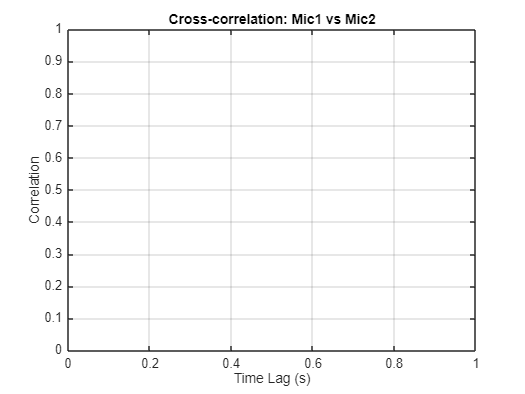

% Cross-correlation

% Mic 1&2
[xc12, lags12] = xcorr(mic1_f, mic2_f,Fs);
% [xc12, lags12] = gccphat(mic1_f, mic2_f,Fs);

[~, idx12] = max(abs(xc12));
lag12 = lags12(idx12);
delay12 = lag12 / Fs;

figure;
plot(lags12/Fs, xc12);
xlabel('Time Lag (s)');
ylabel('Correlation');
title('Cross-correlation: Mic1 vs Mic2');
grid on;

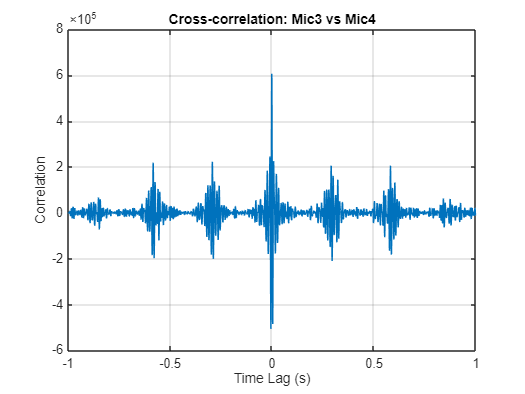


% Mic 3&4
[xc34, lags34] = xcorr(mic3_f, mic4_f,Fs);
%[xc34, lags34] = gccphat(mic3_f, mic4_f,Fs);

[~, idx34] = max(abs(xc34));
lag34 = lags34(idx34);
delay34 = lag34 / Fs;

figure;
plot(lags34/Fs, xc34);
xlabel('Time Lag (s)');
ylabel('Correlation');
title('Cross-correlation: Mic3 vs Mic4');
grid on;


fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);

Delay Mic1-Mic2: -1.000000 s


fprintf('Delay Mic3-Mic4: %.6f s\n', delay34);

Delay Mic3-Mic4: -0.000606 s


L = 0.3;
c = 343;

%delay12
val12 = c *delay12 / L;
fprintf('Val Mic1-Mic2: %.6f s\n', val12);

Val Mic1-Mic2: -1143.333333 s


val12 = max(min(val12, 1), -1);   % clamp to [-1,1]

%delay34
val34 = c *delay34 / L;
fprintf('Val Mic-Mic4: %.6f s\n', val34);

Val Mic-Mic4: -0.692929 s


val34 = max(min(val34, 1), -1);   % clamp to [-1,1]

phi12 = rad2deg(asin(val12))

phi12 = -90

phi34 = rad2deg(asin(val34))

phi34 = -43.8624

% phi12 = rad2deg(asin(c*delay12/L))
